# JHU bootcamp 2019: Ahrens lab -- Analysis of whole-brain neural dynamics 

## 1. Course overview

This course aims to provide an understanding of how to analyze large-scale neural activity in behaving animals. In this experiment, zebrafish adapt their swimming patterns while the visual stimuli move forward, backward and stop. We recorded neural activity across the entire brain at single-cell resolution during this behavior.

**Figure 1: Zebrafish's swimming behavior and neural activity. Movie is available from this **[**link**](https://github.com/ahrens-lab/JHU_Bootcamp/blob/master/activity_movie.mov)

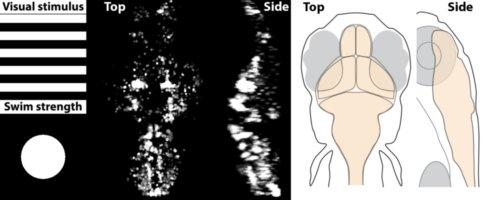

## 2. Goals

In this course, we aim to understand

**(1) basic data handling and plotting skills in Matlab**

**(2) visualization of 3-dimensional data**

**(3) correlation between neural activity and behavioral variables**

**(4) low-dimensionality reduction of large-scale activity data**

## **3. Format**

(i) Mini lectures/discussions

(ii) Coding for basic exercise

(iii) Optional code for advanced exercise

(iv) Q&A for each sections

(v) Advanced discussion on the topics

## **4. Tutors**

Ziqiang Wei (postdoc, Ahrens lab @Janelia) 

Jing Xuan Lim (grad student, Ahrens lab @Janelia)

# Section 1: Load and plot data

## 1.0 Download the data

Please download the data from this [link](https://figshare.com/s/1f7c6c7565e2cf4ae705) to your computer.

## 1.1 Load data

clear variables; close all; %% clear all variables & close all windows

% set Data folder location, e.g.
root_dir='Data/';

load([root_dir,'behavioral_variables.mat']);
load([root_dir,'selected_neural_data.mat']);
load([root_dir,'colortable.mat']);

% Getting the dimension of the volume
dim=size(Volume);  

% Getting the number of cells
cellnum=size(neural_response_matrix,1);

% Getting the number of timepoints
T_max=size(neural_response_matrix,2);


## **1. 2 Data structure**

## **1.2.1 Behavioral data structure**

"swim_power"                     -> Swimming power of fish

"visual_forward"                  -> Forward movement of visual stimuli

"visual_backward"              -> Backward movement of visual stimuli

### Plot behavioral variables

disp('Plot behavioral variables');

Plot behavioral variables


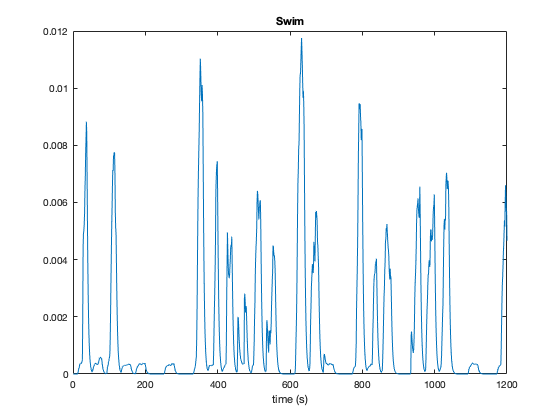


% Plot swim power
plot(swim_power);xlabel('time (s)');title('Swim')

### Exercise 1.1

- Plot forward visual stimuli

- Plot backward visual stimuli

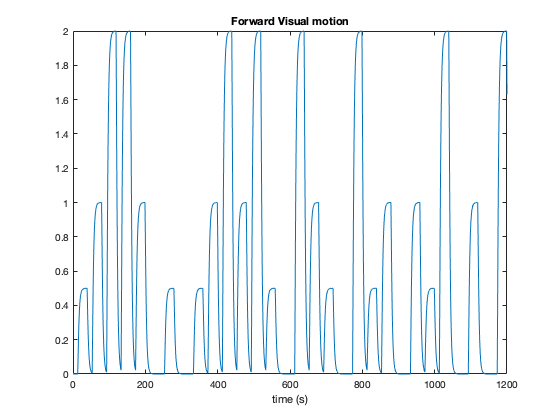

% Plot forward visual stimuli

% Plot backward visual stimuli


## 1.2.2 Neural data structure

"neural_response_matrix"  -> 2D matrix(neuron number, time)

"neural_position_XYZ"       -> 2D matrix(neuron number, location of cell)

"Volume"                            -> Averaged 3D volum

### Plot neural activity

- Plot the neural activity of cell #1 to #10

disp('Plot neural activity');

plot(neural_response_matrix(1:10,:)')

### Exercise 1.2

- Plot activity of next 10 cells

- Plot activity of all cells

% Plot activity of next 10 cells (Exercise)

% Plot activity of all cells (Exercise)


Plot neural activity


## 2.3* Simple yet advanced analysis of neural data -- triggered average

- Swim triggered averag

- Stimulus triggered average

### Exercise 1.3* Compute a triggered average of an example cell #2415

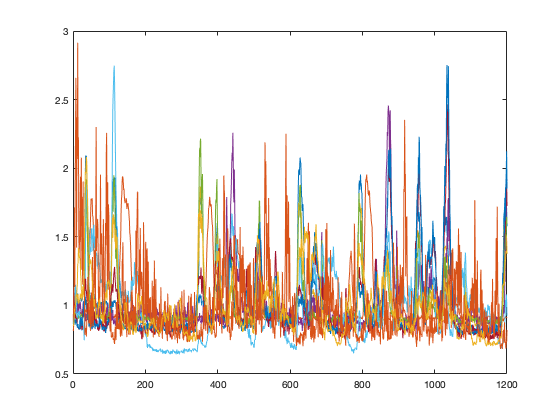

figure;

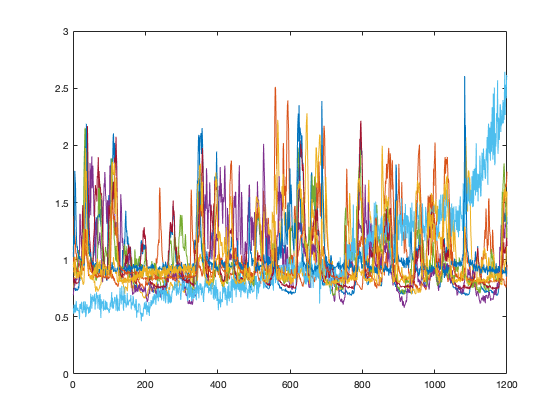

hold on
% plot cell activity
plot(neural_response_matrix(2415, :))


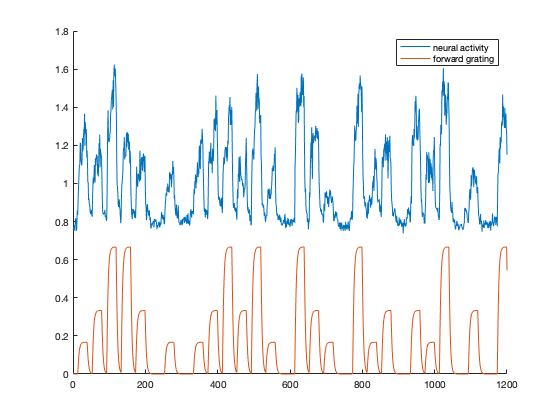

% plot forward grating
plot(forward_stimuli/3)

legend('neural activity', 'forward grating')

% classify the type of forward grating into different categories (e.g. low
% gain and high gain conditions)


% find the timing of onsets at high gain condition

% compute the average of neural dynamics across high gain condition trials
% -- high-gain stimulus triggered average

% try to compute the other trial type


% make comparisons of triggered average in different conditions



# Section 2: Visualization and indexing of a 3-dimensional volume

## 2.1 Projections

Multiple ways of projecting a 3D volume (XYZ) to a 2D image?

         - Maximum, Minimum, Sum, Average....

         - **Advanced discussion** -- Pros and cons for each method

## 2.2 Indexing

Two ways of specifing a point in a 3D volume.

        - Linear index (e.g., array(i)) and subscript (e.g., array(x,y,z))

        - Pros anc cons

**Figure 2: linear index and subscript**

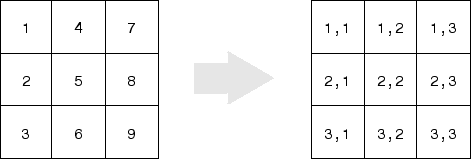

## 2.3 Visualization

### 2.3.1 Plot volume projections from the top

- Top view -- projection along z direction

- Projection method -- sum

disp('Brain visualization')

Brain visualization


% Top projection view
Volume_XY=sum(Volume,3);
Volume_XY=squeeze(Volume_XY);

% Show top view
figure(1);
subplot(1,2,1);
imagesc(Volume_XY);
title('XY')
colormap('gray')  

### Exercise 2.1 Plot volume projections from the side

- Side view -- projection along y direction

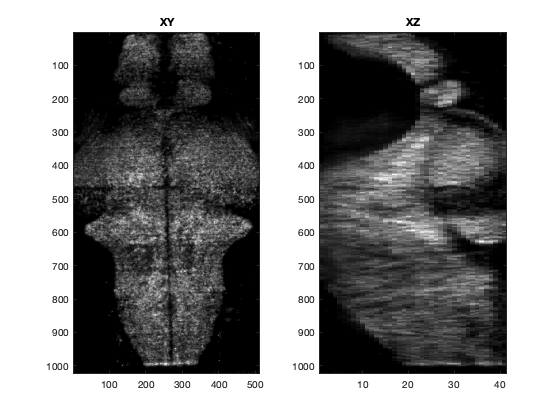

% Side projection view
Volume_XZ=

% Show side view
subplot(1,2,2);
imagesc(Volume_XZ);
title('XZ')
colormap('gray')  

### Exercise 2.2* Plot volume projections from the top/side

- Top view -- projection along z direction

- Side view -- projection along y direction

- Projection method -- Maximum, Minimum, Sum, Average ....

- **Hint**: useful matlab functions -- **max**, **min**, **sum**, **mean** .... 

### Exercise 2.3* **Advanced discussion** -- Pros and cons for each method 

disp('Advanced visualization')

Advanced visualization


% Top/side projection view

% Show top/side view

### 2.3.2 Plot a single cell to its location from the top view

- Get location of cell #1 from **neural_position_XYZ** variable

- Place the cell on the top view

disp('Cell location visualization')

Cell location visualization


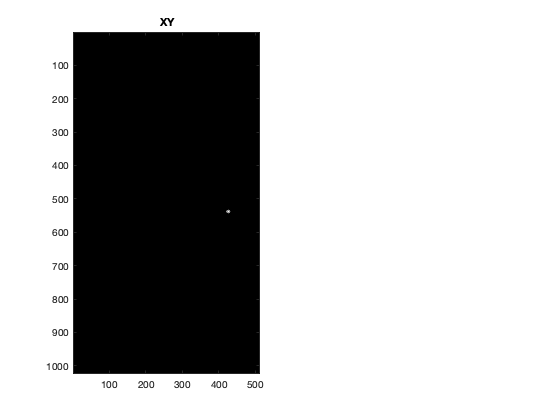


% plot location of cell #1 using linear index 
cell_map1=zeros(dim(1),dim(2),dim(3));
cell_map1(neural_position_XYZ(1,:))=1;

% Top projection view of the cell
cell_map1_XY=sum(cell_map1,3);
cell_map1_XY=squeeze(cell_map1_XY);

% Show top view
figure(2);
subplot(1,2,1);
imagesc(cell_map1_XY);
title('XY')
colormap('gray')  

### Exercise 2.4 Plot a single cell to its location from the side view

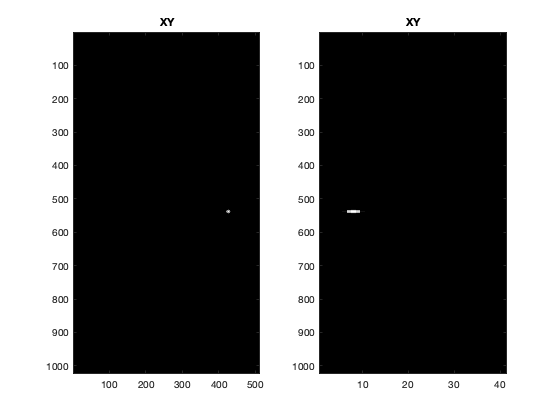

% Side projection view
cell_map1_XZ=

% Show side view
subplot(1,2,2);
imagesc(cell_map1_XZ);
title('XY')
colormap('gray')  

### Exercise 2.5* Place cell on the top view by creating a roi in Matlab

Hint of a solution:

- Image can be presented in RGB format

- Put top view image in red channel and put cell in the green channel

### Exercise 2.6 Plot all cells

- Top view

- Side view

- **Hint**: **for**-loop in matlab

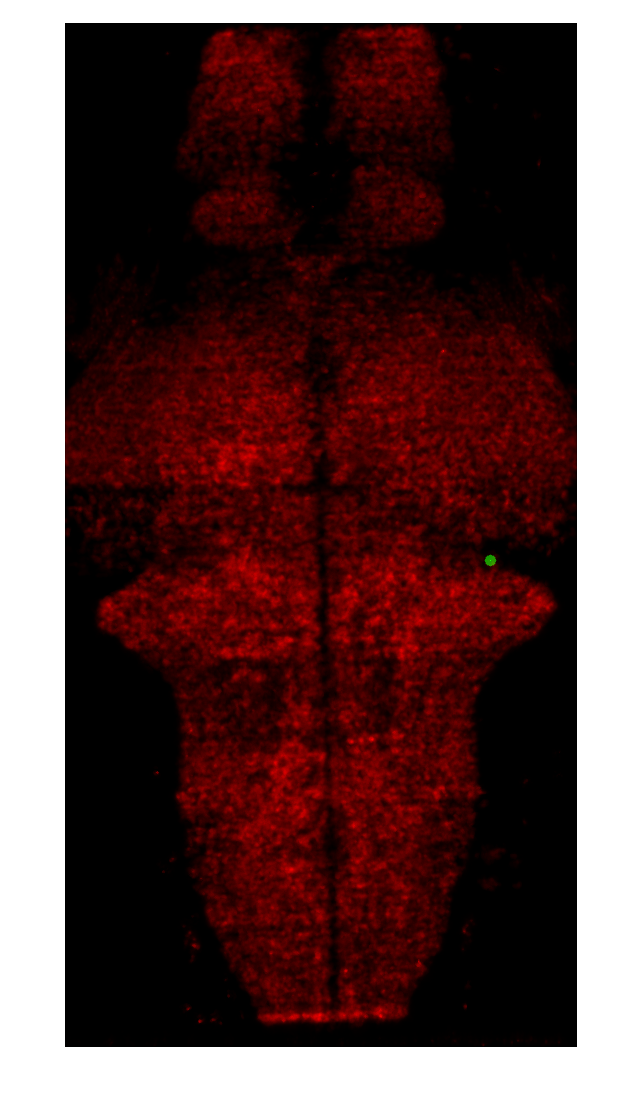

% plot locations of all cells using linear index
% use loop over neurons
cell_map2=zeros(dim(1),dim(2),dim(3));



% Top projection view (Exercise)
cell_map2_XY=

% Side projection view  (Exercise)
cell_map2_XZ=

% Show top view
figure;
subplot(1,2,1);
imagesc(cell_map2_XY);
title('XY')
colormap('gray') 

% Show side view
subplot(1,2,2);
imagesc(cell_map2_XZ);
title('XY')
colormap('gray') 

# Section 3: Correlation with behavioral variables

## (1) Pearson's correlation coefficient *ρ* 


$$\rho_{X,Y} =\frac{\mathrm{Cov}\left(X,Y\right)}{\sigma_X \sigma_Y }=\frac{E\left\lbrack \left(X-\mu_X \right)\left(Y-\mu_Y \right)\right\rbrack }{\sigma_X \sigma_Y }\text{ }$$


- Cov is covariance, E is expectation

- $\mu_X$, $\mu_Y$ is the mean of *X*, *Y*

- $\sigma_X$, $\sigma_Y$ is the standard deviation of *X*, *Y*

## **(2) Multiple linear regression**


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 +\ldotp \ldotp \ldotp \ldotp$$


- $X_1$, $X_2$, ... are different variables

- $\beta_0$ is constant (intercept)

- $\beta_1$, $\beta_2$,.... are regression coefficients

## (3) Pairwise correlation v.s. multiple regression

        - Difference between the two

        - Meaning of Z-scoring

        - Pros anc cons

## 3.1 Z-score behavioral variables

- Hint: **zscore** function 

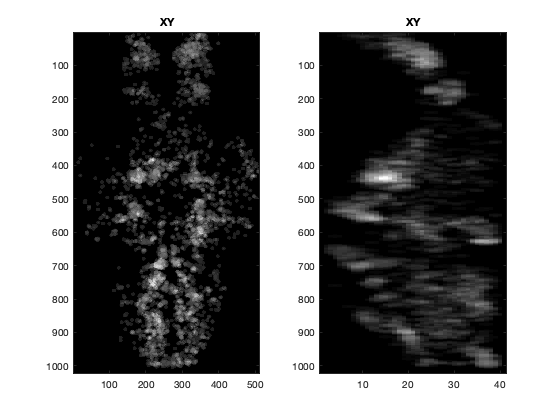

% Z-score the swim power
swim_power_norm=zscore(swim_power);

% Z-score the forward stimuli (Exercise)



% Z-score the backward stimuli (Exercise)



## 3.2 Z-score neural responses (Exercise)

% Z-score the neural response



## 3.3 Calculate correlations between swim power and neural responses

- Hint: **corrcoef** function

- Hint: **corr** function

correlation_neuron_swim = corr(neural_response_matrix_norm', swim_power_norm');

## 3.4 Calculate correlations between forward/backward visual stimuli (Exercise)

% Calculate correlations between forward/backward visual stimuli (Exercise)
correlation_neuron_forward= 
correlation_neuron_backward=

## 3.5 Create correlation map across the whole brain using blue-red colormap

#### Colormap

"blue_red"                          -> Colormap which change like blue-white-red

% Mimic the code used in "Show Cell locations" above.
% Insert correlation values instead of 1

% Plot correlation coefficient in spatial map (Exercise)

cell_map1=zeros(dim(1),dim(2),dim(3)); 


% Top projection view (Exercise)
cell_map_XY1=

% Side projection view (Exercise)
cell_map_XZ1=

% Show top and side views
figure;

subplot(1,6,1);imagesc(cell_map_XY1,[-1 1]);
title('Swim')
subplot(1,6,2);imagesc(squeeze(cell_map_XZ1),[-1 1]);
colormap(blue_red);colorbar;


%% Show correlation map to forward stimuli  (Exercise)
cell_map2=zeros(dim(1),dim(2),dim(3),'single');


% Top projection view  (Exercise)
cell_map_XY2=

% Side projection view (Exercise)
cell_map_XZ2=

% Show top and side views (Exercise)
subplot(1,6,3);
imagesc(cell_map_XY2,[-1 1]);
title('Visual Forward')

subplot(1,6,4);
imagesc(squeeze(cell_map_XZ2),[-1 1]);
colormap(blue_red);colorbar;

%% Show correlation map to backward stimuli  (Exercise)
cell_map3=zeros(dim(1),dim(2),dim(3),'single');


% Top projection view (Exercise)
cell_map_XY3=

% Side projection view (Exercise)
cell_map_XZ3=

% Show top and side views (Exercise)
subplot(1,6,5);
imagesc(cell_map_XY3,[-1 1]);
title('Visual Backward')

subplot(1,6,6);
imagesc(squeeze(cell_map_XZ3),[-1 1]);
colormap(blue_red);colorbar;


## 3.6* Use multivariate regression to neural responses

- Hint: use **regress**,** mvregress** funciton

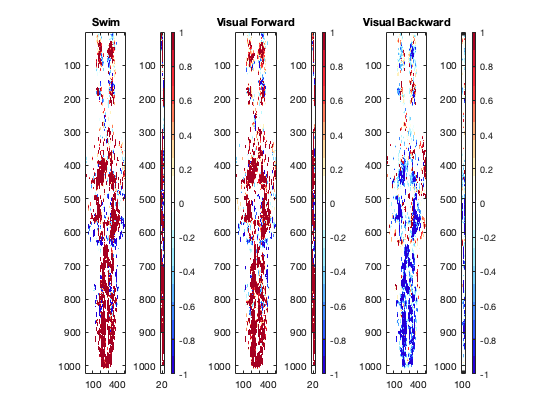

% prepare regressor vector, including intercept

regressor=[swim_power_norm; visual_forward_norm; visual_backward_norm; ones(1,1200)]';

% calculate beta for each regressor (Exercise)
betas=zeros(cellnum,4);


% Show spatial regression map to swim power (Exercise)

cell_map4=zeros(dim(1),dim(2),dim(3),'single');


cell_map_XY4=

cell_map_XZ4=

figure;

subplot(1,6,1);imagesc(cell_map_XY4,[-1 1]);

title('Swim')
subplot(1,6,2);imagesc(squeeze(cell_map_XZ4),[-1 1]);
colormap(blue_red);colorbar;

% Show spatial regression map to forward stimuli (Exercise)

cell_map5=zeros(dim(1),dim(2),dim(3),'single');


cell_map_XY5=

cell_map_XZ5=

subplot(1,6,3);imagesc(cell_map_XY5,[-1 1]);
title('Visual Forward')
subplot(1,6,4);imagesc(squeeze(cell_map_XZ5),[-1 1]);
colormap(blue_red);colorbar;


% Show spatial regression map to backward stimuli (Exercise)

cell_map6=zeros(dim(1),dim(2),dim(3),'single');


cell_map_XY6=

cell_map_XZ6=

subplot(1,6,5);imagesc(cell_map_XY6,[-1 1]);
title('Visual Backward')
subplot(1,6,6);imagesc(squeeze(cell_map_XZ6),[-1 1]);
colormap(blue_red);colorbar;


# Section 4: Dimensionarity reduction

## (1) What is dimensionality reduction? Why necessary?

        - Difficulty of large-scale dataset

        - Difference from regression analysis

## (2) PCA v.s. NMF

        - Difference

        - Pros anc cons

        - What's suited for calcium imaging?

**Figure 3: PCA v.s. NMF of facial images**

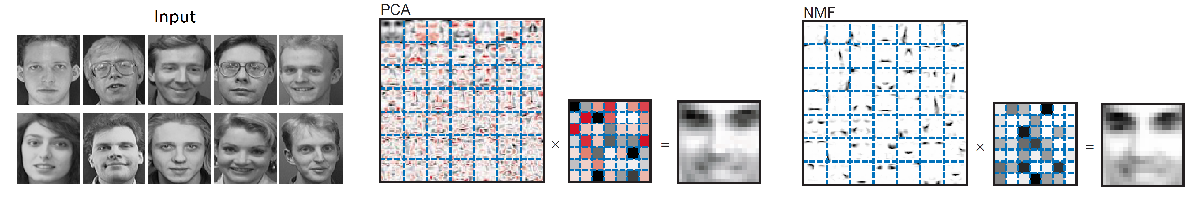

## Principal Component Analysis (PCA) and show maps for each component (Exercise)

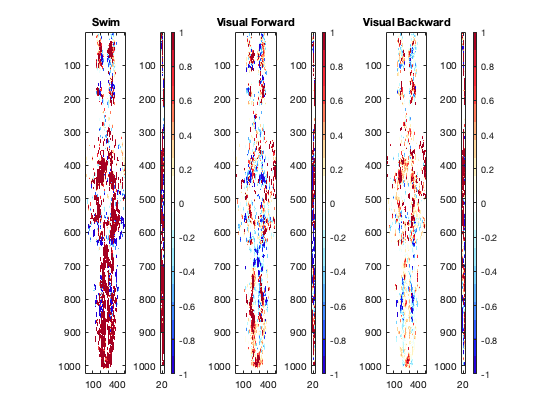

[coeff1,comp1]=pca(neural_response_matrix_norm','NumComponents',3); % 3 PCA components

disp('PCA')
for i=1:3
    
    %% plot PCA coefficient into spatial maps (exercise)
    
    pca_map=zeros(dim(1),dim(2),dim(3));
    %% plot PCA coefficient into spatial maps (exercise)    

    subplot(3, 5, (i-1)*5+1);

    %% top projection (exercise)
    imXY = 
    imagesc(imXY,[-0.25,0.25]);
    colormap(blue_red);
    axis off
    title(['Component ',num2str(i)])

    subplot(3, 5, (i-1)*5+2);

    %% side projection (exercise)
    imXZ = 

    imagesc(imXZ,[-1 1]);
    colormap(blue_red);
    axis off

    subplot(3, 5, (i-1)*5+[3 4 5]);

    %% plot principal component (exercise)
    
    
end

## Non-Negative Matrix Factorization (NNMF) and show maps for each component

rng(3,'twister') %% initialize to a specific seed
[comp2, coeff2]=nnmf(neural_response_matrix_norm',3);


PCA


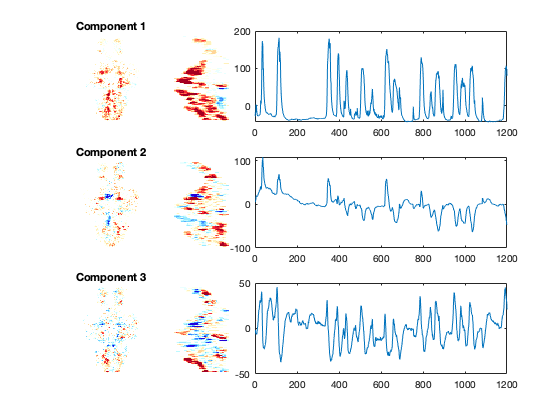

disp('NMF')

for i=1:3
    
    nmf_map=zeros(dim(1),dim(2),dim(3));
    %% plot NMF coefficient into spatial maps (exercise)

    
    subplot(3, 5, (i-1)*5+1);
    
    %% top projection (exercise)
    imXY=
    imagesc(imXY,[-0.25,0.25]);
    colormap(blue_red);
    axis off
    title(['Component ',num2str(i)])
    
    subplot(3, 5, (i-1)*5+2);
    
    %% side projection (exercise)
    imXZ=
    imagesc(imXZ,[-1 1]);
    colormap(blue_red);
    axis off
    
    subplot(3, 5, (i-1)*5+[3 4 5]);
    
    %% plot NMF component (exercise)

    

NMF


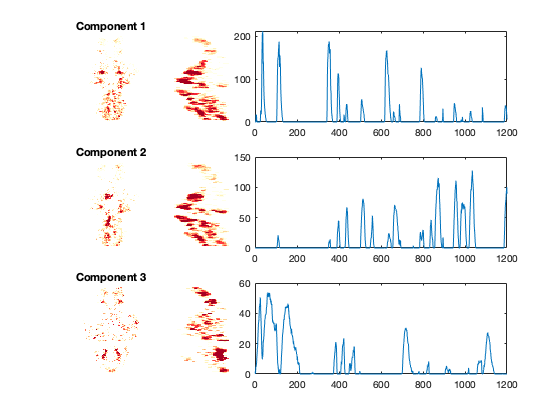

end